Experiment 1

format default

Resultats experimentals

Resultats1 = readtable("Resultados_IA.xlsx", "Sheet","Experiment 1");

Resultats1 = Resultats1(1:10, 1:5)

Resultats1 = 10×5 table
       Seed       MourePrincipi_Distancia_    MoureFinal_Distancia_    MourePrincipi_Temps_    MoureFinal_Temps_
    __________    ________________________    _____________________    ____________________    _________________

         10323             10039                       9919                    7160                   8516      
         72718             10772                      10707                    9062                   9530      
     1.109e+05             11362                      10876                    7891                  10143      
         31416             10868                      10614                    8397                   8912      
      1.51e+05             10382                      10424                    7905                   7186      
     1.009e+05

Boxplots dels resultats

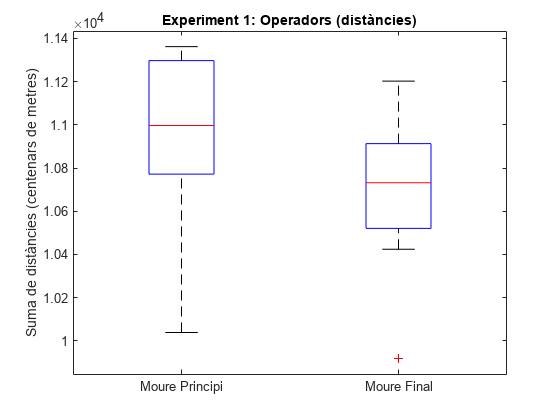

boxplot([Resultats1.MourePrincipi_Distancia_ Resultats1.MoureFinal_Distancia_], 'Labels',{'Moure Principi','Moure Final'})
title("Experiment 1: Operadors (distàncies)");
ylabel("Suma de distàncies (centenars de metres)");

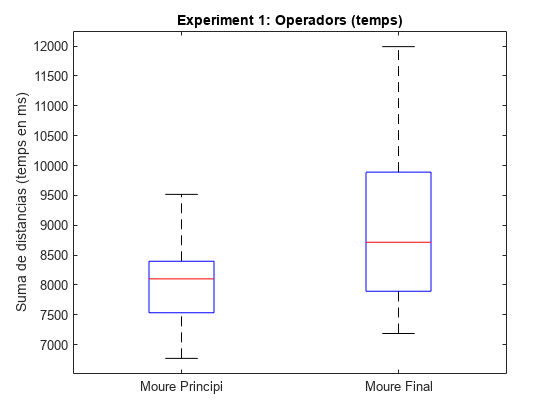


boxplot([Resultats1.MourePrincipi_Temps_ Resultats1.MoureFinal_Temps_], 'Labels',{'Moure Principi','Moure Final'})
title("Experiment 1: Operadors (temps)");
ylabel("Suma de distancias (temps en ms)");


mitjanes = [mean(Resultats1.MourePrincipi_Distancia_), mean(Resultats1.MoureFinal_Distancia_); mean(Resultats1.MourePrincipi_Temps_./1000) mean(Resultats1.MoureFinal_Temps_./1000)];
array2table(mitjanes, "VariableNames",{'Moure principi', 'Moure final'}, "RowNames", ["Suma de distàncies (centenars de metres)", "Temps (en s)"]);

t-test per comprobar les hipòtesis nules.

[h, p, ci, stats] = ttest(Resultats1.MourePrincipi_Distancia_, Resultats1.MoureFinal_Distancia_, "Alpha",0.05)

h = 1

p = 0.0061

ci =    80.0091
  358.5909


stats = struct with fields:
    tstat: 3.5615
       df: 9
       sd: 194.7152


[h2, p2, ci2, stats2] = ttest(Resultats1.MourePrincipi_Temps_ , Resultats1.MoureFinal_Temps_, "Alpha",0.05)

h2 = 1

p2 = 0.0448

ci2 = 1.0e+03 *

   -1.8133
   -0.0265


stats2 = struct with fields:
    tstat: -2.3292
       df: 9
       sd: 1.2489e+03


Experiment 2: Greedy vs Random

Resultats2 = readtable("Resultados_IA.xlsx", "Sheet","Experiment 2");

Resultats2 = Resultats2(1:10, 1:5)

Resultats2 = 10×5 table
       Seed       GREEDY    RANDOM_MitjanaDe5_    TempsGreedy    TempsRandom_MitjanaDe5_
    __________    ______    __________________    ___________    _______________________

         10324    10656           10805              10886                10692         
         72719    10452           10572               7940                 9301         
     1.109e+05    10667           10598               9921                11070         
         31417    10293           10272               8603                11636         
      1.51e+05    10903           11080               9342                 9903         
     1.009e+05    10555           10769               9470                10618         
     2.012e+05    10834           11280              10613                 9969         
    

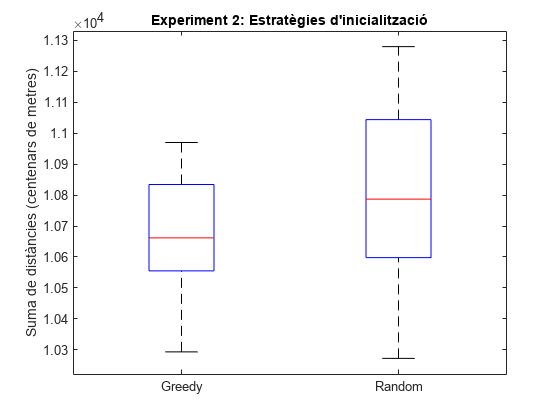


boxplot([Resultats2.GREEDY Resultats2.RANDOM_MitjanaDe5_], 'Labels',{'Greedy','Random'})
title("Experiment 2: Estratègies d'inicialització")
ylabel("Suma de distàncies (centenars de metres)")

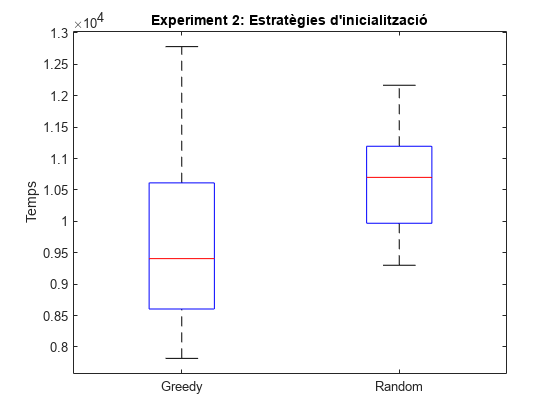


boxplot([Resultats2.TempsGreedy Resultats2.TempsRandom_MitjanaDe5_], 'Labels',{'Greedy','Random'})
title("Experiment 2: Estratègies d'inicialització")
ylabel("Temps")


mitjanes = [mean(Resultats2.GREEDY), mean(Resultats2.RANDOM_MitjanaDe5_); mean(Resultats2.TempsGreedy./1000) mean(Resultats2.TempsRandom_MitjanaDe5_./1000)];
array2table(mitjanes, "VariableNames",{'Greedy', 'Random'}, "RowNames", ["Suma de distàncies (centenars de metres)", "Temps (en s)"])

ans = 2×2 table
                                                Greedy    Random
                                                ______    ______

    Suma de distàncies (centenars de metres)     10669     10813
    Temps (en s)                                9.6475    10.726



[h,p,interval,stats] = ttest(Resultats2.GREEDY, Resultats2.RANDOM_MitjanaDe5_,"Tail","right")

h = 0

p = 0.9839

interval =  -248.5386
       Inf


stats = struct with fields:
    tstat: -2.5293
       df: 9
       sd: 180.1656


[ht,pt,intervalT,statsT] = ttest(Resultats2.TempsGreedy, Resultats2.TempsRandom_MitjanaDe5_,"Tail","right")

ht = 0

pt = 0.9847

intervalT = 1.0e+03 *

   -1.8498
       Inf


statsT = struct with fields:
    tstat: -2.5615
       df: 9
       sd: 1.3311e+03


Experiment 3: Lambda-Experimentació

Resultats3 = readtable("Resultados_IA.xlsx", "Sheet","Experiment 3");

Resultats3 = Resultats3(1:10, 1:4)

Resultats3 = 10×4 table
       Seed       Lambda_0_5    Lambda_1    Lambda_2
    __________    __________    ________    ________

         20646      10548        10576       10872  
    1.4544e+05      10702        10702       10718  
     2.218e+05      10630        10630       10630  
         62832      10327        10516       10430  
      3.02e+05      10634        10634       10607  
     2.018e+05      10622        10377       10781  
     4.024e+05      10306        10298       10630  
         41804       9962         9962        9962  
    1.0271e+08      10795        10777       10867  
    9.7582e+05      10369        10369       10429  


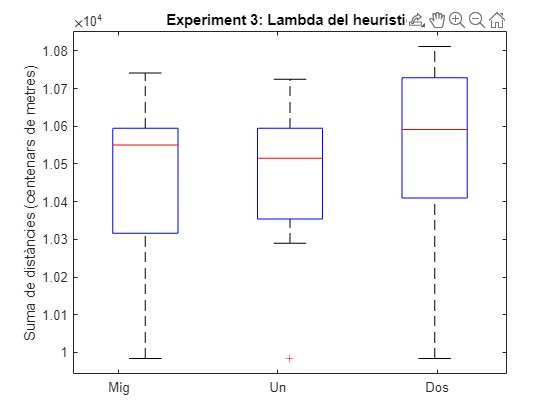


boxplot([Resultats3.Lambda_0_5, Resultats3.Lambda_1, Resultats3.Lambda_2], 'Labels',{'Mig','Un', 'Dos'})
title("Experiment 3: Lambda del heurístic")
ylabel("Suma de distàncies (centenars de metres)")


[h1,p1,interval1,stats1] = ttest(Resultats3.Lambda_0_5,  Resultats3.Lambda_1)

h1 = 0

p1 = 0.8727

interval1 =   -68.7224
   79.5224


stats1 = struct with fields:
    tstat: 0.1648
       df: 9
       sd: 103.6160


[h2,p2,interval2, stats2] = ttest(Resultats3.Lambda_1, Resultats3.Lambda_2)

h2 = 0

p2 = 0.0759

interval2 =  -230.8831
   13.8831


stats2 = struct with fields:
    tstat: -2.0055
       df: 9
       sd: 171.0797


[h3,p3,interval3,stats3] = ttest(Resultats3.Lambda_0_5, Resultats3.Lambda_2)

h3 = 1

p3 = 0.0322

interval3 =  -195.2410
  -10.9590


stats3 = struct with fields:
    tstat: -2.5312
       df: 9
       sd: 128.8043


Experiment  4: Guerra d'Heurístics

Resultats4 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 4");

Resultats4 = Resultats4(1:10, 1:4)

Resultats4 = 10×4 table
       Seed       SumaDistancia    Entropia    Lambda_1
    __________    _____________    ________    ________

          5161        10752         10791       10813  
         36359         9926         10471        9904  
         55450        10738         11125       10692  
         15708        11133         11196       10979  
         75501        10759         10961       10617  
         50451        10348         10725       10288  
     1.006e+05        10378         10903       10792  
         10451        10220         10330       10235  
    2.5677e+07        10707         10986       10781  
    2.4396e+05        11162         11724       11280  


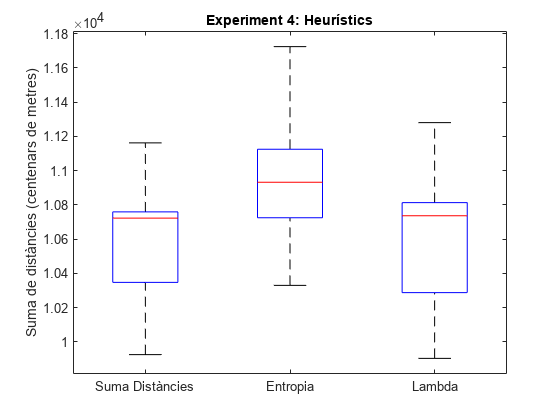


boxplot([Resultats4.SumaDistancia, Resultats4.Entropia, Resultats4.Lambda_1], 'Labels',{'Suma Distàncies','Entropia', 'Lambda'})
title("Experiment 4: Heurístics")
ylabel("Suma de distàncies (centenars de metres)")


[h1,p1,interval1,stats1] = ttest(Resultats4.SumaDistancia, Resultats4.Entropia)

h1 = 1

p1 = 8.8633e-04

interval1 =  -452.4544
 -165.3456


stats1 = struct with fields:
    tstat: -4.8677
       df: 9
       sd: 200.6752


[h2,p2,interval2,stats2] = ttest( Resultats4.Entropia, Resultats4.Lambda_1)

h2 = 1

p2 = 0.0011

interval2 =   147.1807
  419.0193


stats2 = struct with fields:
    tstat: 4.7117
       df: 9
       sd: 190.0020


[h3,p3,interval3,stats3] = ttest(Resultats4.SumaDistancia, Resultats4.Lambda_1)

h3 = 0

p3 = 0.6280

interval3 =  -142.1700
   90.5700


stats3 = struct with fields:
    tstat: -0.5015
       df: 9
       sd: 162.6740


Experiment 5

Resultats5 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5", "ReadVariableNames",true);

Resultats5 = Resultats5(1:10, 1:9)

Resultats5 = 10×9 table
       Seed       x5000    x10000    x50000    x75000    x100000    x150000    x200000     HC  
    __________    _____    ______    ______    ______    _______    _______    _______    _____

         31092    12006    11273     10347     10248      10175      10202      10249     10907
    2.1828e+05    11975    11507     10633     10350      10232      10358      10185     10721
    3.3283e+05    11649    11155     10366     10193      10206      10054       9976     10955
         94371    12074    11400     10513     10105      10342      10083      10027     10709
    4.5313e+05    11559    11209     10229     10066       9960       9984      10126     104

Resultats5_2 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5_2", "ReadVariableNames",true);

Resultats5_2 = Resultats5_2(1:10, 1:13)

Resultats5_2 = 10×13 table
       Seed       k_1_l_1    k_1_l_0_01    k_1_l_0_0001    k_5_l_1    k_5_l_0_01    k_5_l_0_0001    k_25_l_1    k_25_l_0_01    k_25_l_0_0001    k_125_l_1    k_125_l_0_01    k_125_l_0_0001
    __________    _______    __________    ____________    _______    __________    ____________    ________    ___________    _____________    _________    ____________    ______________

          3482     13957       10675          10869         13625       10602          10557         13834         10723           10341          14138   

Resultats5_3 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5_3", "ReadVariableNames",true);

Resultats5_3 = Resultats5_3(1:10, 1:13)

Resultats5_3 = 10×13 table
       Seed       k_15_L_0_001    k_15_L_0_0001    k_15_L_0_00001    k_20_L_0_001    k_20_L_0_0001    k_20_l_0_00001    k_25_L_0_001    k_25_L_0_0001    k_25_L_0_00001    k_30_L_0_001    k_30_L_0_0001    k_30_L_0_00001
    __________    ____________    _____________    ______________    ____________    _____________    ______________    ____________    _____________    ______________    ____________    _____________    ______________

          3482       10532            10645            10433            10710            102

Resultats5_4 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5_4", "ReadVariableNames",true);

Resultats5_4 = Resultats5_4(1:10, 1:13)

Resultats5_4 = 10×13 table
    Seed_Stiter     x50      x75     x100     x150     x200     x250     x300     x500     x750     x1000    x1250    x1500
    ___________    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____

          7373      9989    10129     9994     9993    10038     9929     9987     9952    10054     9965    10096    10092
         51941      9899     9862     9985     9950     9834     9931     9894     9934     9786     9810     9818     9876
         79215      9870     9855 

Resultats5_5 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5_5", "ReadVariableNames",true);

Resultats5_5= Resultats5_5(1:10, 1:12)

Resultats5_5 = 10×12 table
    Seed_Steps    x10000    x30000    x50000    x75000    x100000    x200000    x300000    x500000    x1000000    x2000000     HC  
    __________    ______    ______    ______    ______    _______    _______    _______    _______    ________    ________    _____

         19717    11612     10738     10208     10003      9763       9528       9226       9340        9262        9246      10411
         24516    12229     11337     10592     10078      9750       9607       9553       9567        9590        9583      11034
         27453    11988     10850   

Primer mirem a partir de quin nombre de steps Simmulated annealing supera a Hill Climbing

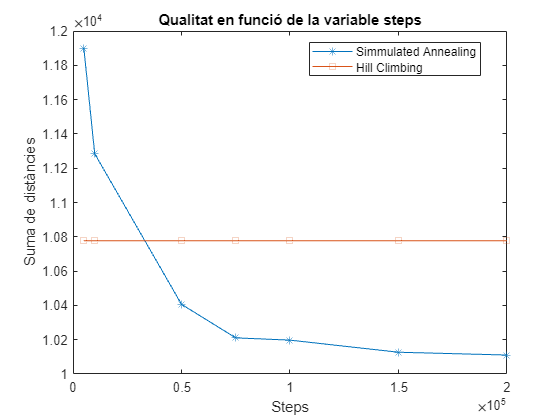

steps = [5000, 10000, 50000, 75000, 100000, 150000, 200000];
distance = [mean(Resultats5.x5000) mean(Resultats5.x10000) mean(Resultats5.x50000) mean(Resultats5.x75000) mean(Resultats5.x100000) mean(Resultats5.x150000) mean(Resultats5.x200000)];
distanceHC = [mean(Resultats5.HC) mean(Resultats5.HC) mean(Resultats5.HC) mean(Resultats5.HC) mean(Resultats5.HC) mean(Resultats5.HC) mean(Resultats5.HC)];
plot(steps, distance, "*-",steps, distanceHC, "s-");
title("Qualitat en funció de la variable steps");
legend("Simmulated Annealing", "Hill Climbing");
xlabel("Steps");
ylabel("Suma de distàncies");

legend("Position", [0.5503,0.82024,0.31071,0.077381]);

Desprès experimentem amb diversos valors de K i lambda

X = [mean(Resultats5_2.k_1_l_1) mean(Resultats5_2.k_5_l_1) mean(Resultats5_2.k_25_l_1) mean(Resultats5_2.k_125_l_1);
     mean(Resultats5_2.k_1_l_0_01) mean(Resultats5_2.k_5_l_0_01) mean(Resultats5_2.k_25_l_0_01) mean(Resultats5_2.k_125_l_0_01);
     mean(Resultats5_2.k_1_l_0_0001) mean(Resultats5_2.k_5_l_0_0001) mean(Resultats5_2.k_25_l_0_0001) mean(Resultats5_2.k_125_l_0_0001)];

Unable to resolve the name 'Resultats5_2.k_1_l_1'.

bar3(X');
set(gca,'XTickLabel',[1 0.01 0.0001]);
set(gca,'YTickLabel',[1 5 25 125]);

X2 = X(2:3, :);
bar3(X2');
set(gca,'XTickLabel',[0.01 0.0001]);
set(gca,'YTickLabel',[1 5 25 125]);

Ara ens centrem alrededor del punt K = 25 i lambda = 0.0001

X = [mean(Resultats5_3.k_15_L_0_001) mean(Resultats5_3.k_20_L_0_001) mean(Resultats5_3.k_25_L_0_001) mean(Resultats5_3.k_30_L_0_001);
     mean(Resultats5_3.k_15_L_0_0001) mean(Resultats5_3.k_20_L_0_0001) mean(Resultats5_3.k_25_L_0_0001) mean(Resultats5_3.k_30_L_0_0001);
     mean(Resultats5_3.k_15_L_0_00001) mean(Resultats5_3.k_20_l_0_00001) mean(Resultats5_3.k_25_L_0_00001) mean(Resultats5_3.k_30_L_0_00001)];
X

X = 1.0e+04 *

    1.0351    1.0356    1.0340    1.0267
    1.0159    1.0038    1.0021    0.9989
    0.9953    1.0203    1.0550    1.0832


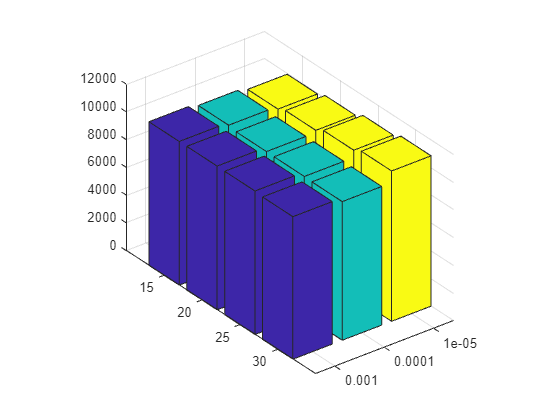

bar3(X');
set(gca,'XTickLabel',[0.001 0.0001 0.00001]);
set(gca,'YTickLabel',[15 20 25 30]);

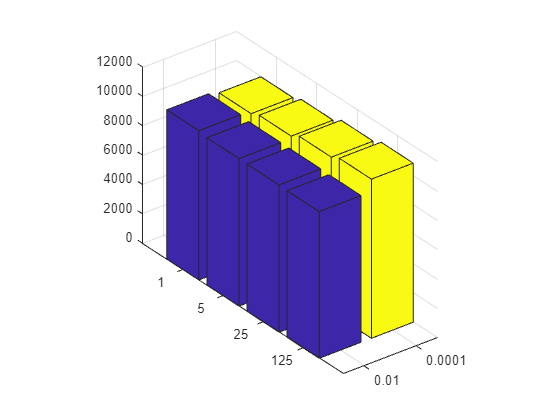


X2 = X(2:3, :);
bar3(X2');
set(gca,'XTickLabel',[0.01 0.0001]);
set(gca,'YTickLabel',[1 5 25 125]);

Fixem K = 15 i lambda = 0.0001 i experimentem amb el stiter

stiter = [50 75 100 150 200 250 300 500 750 1000 1250 1500];
resultatsStiter = [mean(Resultats5_4.x50) mean(Resultats5_4.x75) mean(Resultats5_4.x100) mean(Resultats5_4.x150) mean(Resultats5_4.x200) mean(Resultats5_4.x250) mean(Resultats5_4.x300) mean(Resultats5_4.x500) mean(Resultats5_4.x750) mean(Resultats5_4.x1000) mean(Resultats5_4.x1250) mean(Resultats5_4.x1500)]

resultatsStiter = 1.0e+03 *

    9.8762    9.8931    9.8943    9.8865    9.8233    9.8647    9.9058    9.8847    9.8461    9.8481    9.8953    9.8576


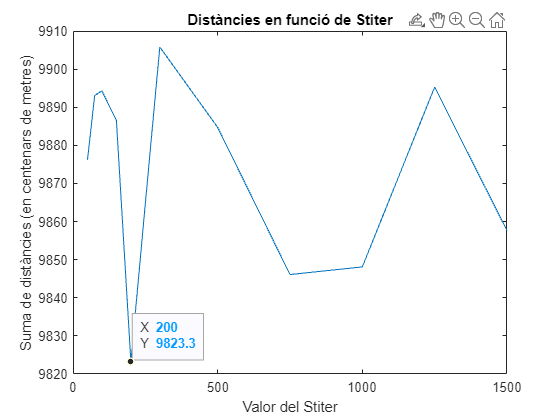

plot(stiter, resultatsStiter);
title("Distàncies en funció de Stiter");
xlabel("Valor del Stiter");
ylabel("Suma de distàncies (en centenars de metres)");

ax = gca;
chart = ax.Children(1);
datatip(chart,200,9823);

Fixem el stiter a 200 i tornem a probar amb els steps

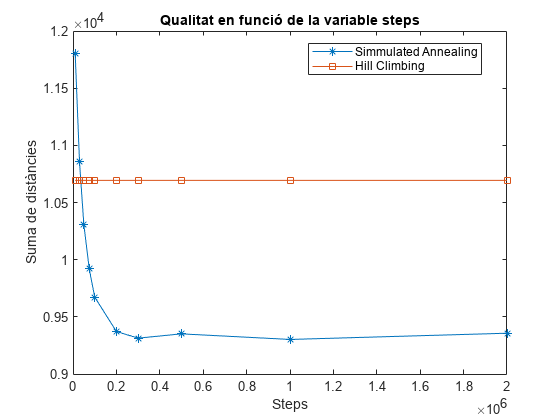

steps2 = [10000	30000	50000	75000	100000	200000	300000	500000	1000000	2000000];
distance2 = [mean(Resultats5_5.x10000) mean(Resultats5_5.x30000) mean(Resultats5_5.x50000) mean(Resultats5_5.x75000) mean(Resultats5_5.x100000) mean(Resultats5_5.x200000) mean(Resultats5_5.x300000) mean(Resultats5_5.x500000)  mean(Resultats5_5.x1000000) mean(Resultats5_5.x2000000)];
distanceHC2 = [mean(Resultats5_5.HC) mean(Resultats5_5.HC) mean(Resultats5_5.HC) mean(Resultats5_5.HC) mean(Resultats5_5.HC) mean(Resultats5_5.HC) mean(Resultats5_5.HC) mean(Resultats5_5.HC) mean(Resultats5_5.HC) mean(Resultats5_5.HC)];

plot(steps2, distance2, "*-",steps2, distanceHC2, "s-");
title("Qualitat en funció de la variable steps");
legend("Simmulated Annealing", "Hill Climbing");
xlabel("Steps");
ylabel("Suma de distàncies");

legend("Position", [0.5503,0.82024,0.31071,0.077381]);

Experiment 6

Resultats6 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 6", "ReadVariableNames",true);

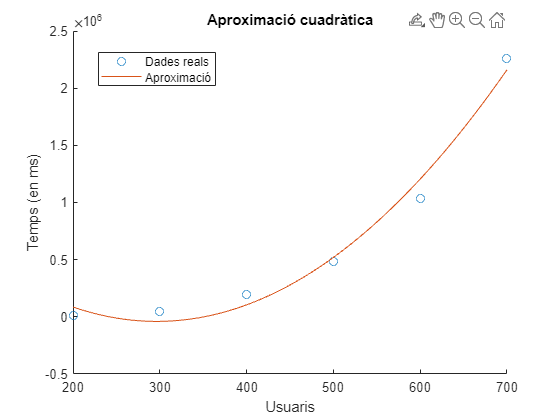

Resultats6 = Resultats6(1:10, 1:7);

format long
x = [200:100:700];
y = [9147.1, 50254.5, 193824.2, 481523.8, 1039274.25, 2263407];
g = polyfit(x, y, 2);
g2 = polyfit(x, y, 3);
g3 = polyfit(x, y, 4);
f = fit(x', y', "exp1");
x2 = linspace(200, 700, 1000);
y2 = polyval(g, x2);
y3 = polyval(g2, x2);
y4 = polyval(g3, x2);
scatter(x, y);
hold on
plot(x2, y2);
title("Aproximació cuadràtica");
xlabel("Usuaris");
ylabel("Temps (en ms)");
legend("Dades reals", "Aproximació");
hold off

legend("Position", [0.1756,0.79484,0.21071,0.082143])

Error2 = sqrt(sum((polyval(g, x) - y).^2))

Error2 =      2.478407817063051e+05


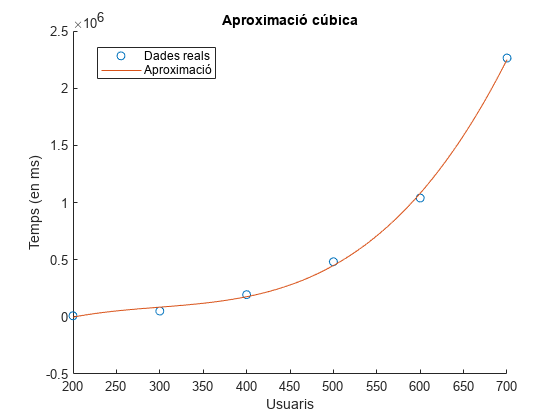


scatter(x, y);
hold on
plot(x2, y3);
title("Aproximació cúbica");
xlabel("Usuaris");
ylabel("Temps (en ms)");
legend("Dades reals", "Aproximació");
hold off

legend("Position", [0.17381,0.81151,0.2125,0.077381])

Error3 = sqrt(sum((polyval(g2, x) - y).^2))

Error3 =      6.804330154241294e+04


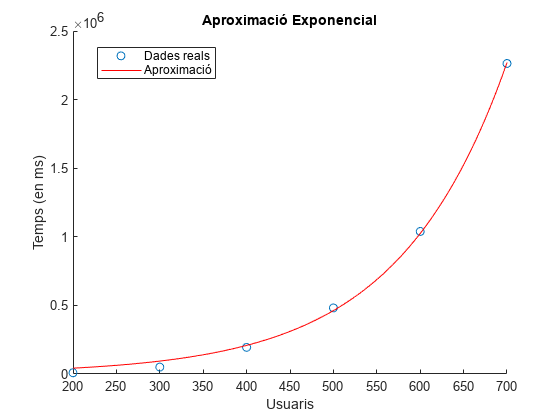


scatter(x, y);
hold on
plot(f);
title("Aproximació Exponencial");
xlabel("Usuaris");
ylabel("Temps (en ms)");
legend("Dades reals", "Aproximació");
hold off

legend("Position", [0.17381,0.81151,0.2125,0.077381])

Error4 = sum((polyval(g3, x) - y).^2)

Error4 =      1.375177956195298e+08



scatter(x, y);
hold on
plot(x2, y4);
title("Aproximació de Grau 4");
xlabel("Usuaris");
ylabel("Temps (en ms)");
legend("Dades reals", "Aproximació");
hold off
sumaRes = (f(x) - y)

sumaRes = 1.0e+06 *

   0.033343588200733  -0.007763811799267  -0.151333511799267  -0.439033111799267  -0.996783561799267  -2.220916311799267
   0.085008709014580   0.043901309014580  -0.099668390985420  -0.387367990985420  -0.945118440985420  -2.169251190985420
   0.199494292893163   0.158386892893163   0.014817192893163  -0.272882407106837  -0.830632857106837  -2.054765607106837
   0.453184765489665   0.412077365489665   0.268507665489665  -0.019191934510335  -0.576942384510335  -1.801075134510335
   1.015341621452347   0.974234221452347   0.830664521452347   0.542964921452347  -0.014785528547653  -1.238918278547654
   2.261034167456949   2.219926767456949   2.076357067456949   1.788657467456949   1.230907017456949   0.006774267456949


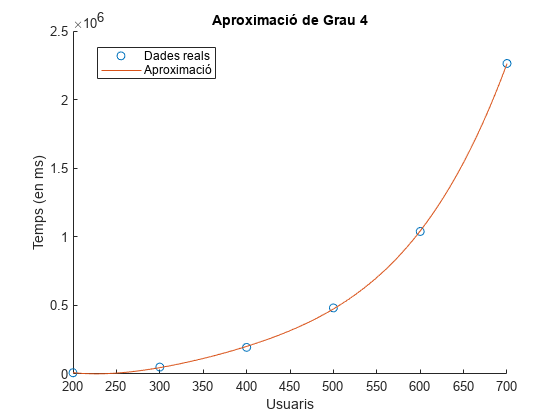


legend("Position", [0.17381,0.81151,0.2125,0.077381])

ErrorExp = sum(SumaRes.^2)

Unrecognized function or variable 'SumaRes'.

%legend("Punts Reals", "Grau 3", "Grau 2", "Grau 4");


Sr2 = y - polyval(g, x);
Sr3 = y - polyval(g2, x);
Sr4 = y - polyval(g3, x);

polyval(g2, 700);
polyval(g3, 700);
g2
g3
Sr = [sum(Sr2.^2)/3 sum(Sr3.^2)/2 sum(Sr4.^2)]
xlim([196 746])
ylim([-582311 2717689])
legend("Position", [0.17381,0.67341,0.22321,0.15595])

Experiment 7

Resultats7_Dist = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 7 Distancia", "ReadVariableNames",true);

Resultats7_Dist = Resultats7_Dist(1:10, 1:4)

Resultats7_Dist = 10×4 table
    Seed_Distancia    SumaDistancias    x_Coches    x_Coches_2
    ______________    ______________    ________    __________

         134199           10617          10544        10809   
         945334           10969          10673        10427   
        1441713           11284          10510        10510   
         408408           10971          10280        10244   
        1963026           10761          10850        10850   
        1311726           10680          10240        10284   
        2615613           10571          10467        10497   
         271726           11221          10925        10851   
      667596956           10894          10369        10528   
        6342856           11077          10582        10088   


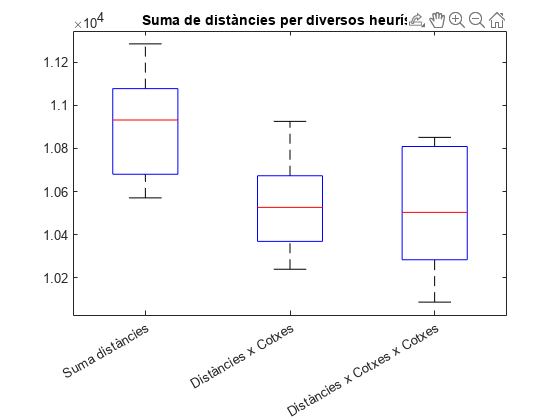


boxplot([Resultats7_Dist.SumaDistancias, Resultats7_Dist.x_Coches, Resultats7_Dist.x_Coches_2],'Labels',{'Suma distàncies','Distàncies x Cotxes', 'Distàncies x Cotxes x Cotxes'});
title("Suma de distàncies per diversos heurístics");


Resultats7_Temps = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 7 Temps", "ReadVariableNames",true);

Resultats7_Temps = Resultats7_Temps(1:10, 1:4)

Resultats7_Temps = 10×4 table
    Seed_Temps    SumaDistancias    x_Coches    x_Coches_2
    __________    ______________    ________    __________

       134199         11857          26789        27071   
       945334         11910          23207        25343   
      1441713         10257          24719        24605   
       408408          9775          25273        25770   
      1963026          9490          18516        18420   
      1311726          9615          26515        27921   
      2615613         11023          24021        22885   
       271726         10899          23870        25090   
    667596956         11129          27053        22544   
      6342856          8966          22286        28151   


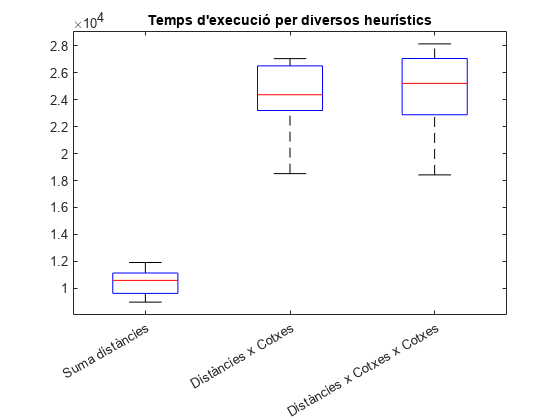


boxplot([Resultats7_Temps.SumaDistancias, Resultats7_Temps.x_Coches, Resultats7_Temps.x_Coches_2],'Labels',{'Suma distàncies','Distàncies x Cotxes', 'Distàncies x Cotxes x Cotxes'});
title("Temps d'execució per diversos heurístics");


Resultats7_Cotxes = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 7 Cotxes", "ReadVariableNames",true);

Resultats7_Cotxes = Resultats7_Cotxes(1:10, 1:4)

Resultats7_Cotxes = 10×4 table
    Seed_Cotxes    SumaDistancias    x_Coches    x_Coches_2
    ___________    ______________    ________    __________

        134199           91             55           54    
        945334           90             56           53    
       1441713           86             57           57    
        408408           92             54           54    
       1963026           95             56           56    
       1311726           92             56           55    
       2615613           87             54           54    
        271726           90             56           56    
     667596956           92             52           55    
       6342856           91             55           53    


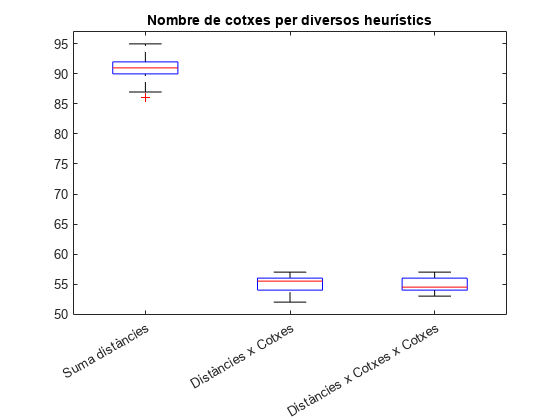


boxplot([Resultats7_Cotxes.SumaDistancias, Resultats7_Cotxes.x_Coches, Resultats7_Cotxes.x_Coches_2],'Labels',{'Suma distàncies','Distàncies x Cotxes', 'Distàncies x Cotxes x Cotxes'});
title("Nombre de cotxes per diversos heurístics");

[hd1,pd1, intervald1, statsd1] = ttest(Resultats7_Dist.SumaDistancias, Resultats7_Dist.x_Coches)

hd1 =      1


pd1 =    0.002614659388303


intervald1 = 1.0e+02 *

   1.623545304005824
   5.586454695994175


statsd1 = struct with fields:
    tstat: 4.115701756075627
       df: 9
       sd: 2.769882668995205e+02


[hd2,pd2, intervald2, statsd2] = ttest(Resultats7_Dist.x_Coches, Resultats7_Dist.x_Coches_2)

hd2 =      0


pd2 =    0.609064916227573


intervald2 = 1.0e+02 *

  -1.150960149408174
   1.854960149408175


statsd2 = struct with fields:
    tstat: 0.529807341610835
       df: 9
       sd: 2.100993415823413e+02


[hd3,pd3, intervald3, statsd3] = ttest(Resultats7_Dist.SumaDistancias, Resultats7_Dist.x_Coches_2)

hd3 =      1


pd3 =    0.009563059295799


intervald3 = 1.0e+02 *

   1.226082810254175
   6.687917189745824


statsd3 = struct with fields:
    tstat: 3.277783715596893
       df: 9
       sd: 3.817558993213682e+02



[ht1,pt1, intervalt1, statst1] = ttest(Resultats7_Temps.SumaDistancias, Resultats7_Temps.x_Coches)

ht1 =      1


pt1 =      1.756906761639308e-08


intervalt1 = 1.0e+04 *

  -1.540700041883867
  -1.205859958116132


statst1 = struct with fields:
    tstat: -18.555575267878766
       df: 9
       sd: 2.340370806327730e+03


[ht2,pt2, intervalt2, statst2] = ttest(Resultats7_Temps.x_Coches, Resultats7_Temps.x_Coches_2)

ht2 =      0


pt2 =    0.518140639271786


intervalt2 = 1.0e+03 *

  -2.422273171156683
   1.312073171156683


statst2 = struct with fields:
    tstat: -0.672526501808819
       df: 9
       sd: 2.610128113075423e+03


[ht3,pt3, intervalt3, statst3] = ttest(Resultats7_Temps.SumaDistancias, Resultats7_Temps.x_Coches_2)

ht3 =      1


pt3 =      1.521448621468569e-07


intervalt3 = 1.0e+04 *

  -1.651826486412600
  -1.205753513587400


statst3 = struct with fields:
    tstat: -14.491564069276189
       df: 9
       sd: 3.117835091141857e+03



[hc1,pc1, intervalc1, statsc1] = ttest(Resultats7_Temps.SumaDistancias, Resultats7_Temps.x_Coches)

hc1 =      1


pc1 =      1.756906761639308e-08


intervalc1 = 1.0e+04 *

  -1.540700041883867
  -1.205859958116132


statsc1 = struct with fields:
    tstat: -18.555575267878766
       df: 9
       sd: 2.340370806327730e+03


[hc2,pt2, intervalc2, statsc2] = ttest(Resultats7_Temps.x_Coches, Resultats7_Temps.x_Coches_2)

hc2 =      0


pt2 =    0.518140639271786


intervalc2 = 1.0e+03 *

  -2.422273171156683
   1.312073171156683


statsc2 = struct with fields:
    tstat: -0.672526501808819
       df: 9
       sd: 2.610128113075423e+03


[hc3,pc3, intervalc3, statsc3] = ttest(Resultats7_Temps.SumaDistancias, Resultats7_Temps.x_Coches_2)

hc3 =      1


pc3 =      1.521448621468569e-07


intervalc3 = 1.0e+04 *

  -1.651826486412600
  -1.205753513587400


statsc3 = struct with fields:
    tstat: -14.491564069276189
       df: 9
       sd: 3.117835091141857e+03


Experiment 8

Resultats8_Dist = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 8 Distancia", "ReadVariableNames",true);

Resultats8_Dist = Resultats8_Dist(1:10, 1:4)

Resultats8_Dist = 10×4 table
    Seed_Distancia    SumaDistancias    x_Coches    x_Coches_2
    ______________    ______________    ________    __________

       1.342e+05           9570          10662        10654   
      9.4533e+05           9406          10876        10301   
      1.4417e+06           9567          10984        10899   
      4.0841e+05           9332          10440         9946   
       1.963e+06           9466          10373        10413   
      1.3117e+06           9327          10656        10520   
      2.6156e+06           9361          10466        10619   
      2.7173e+05           9508          10575        11012   
       6.676e+08           9392          10862        10700   
      6.3429e+06           9264          10643        10170   


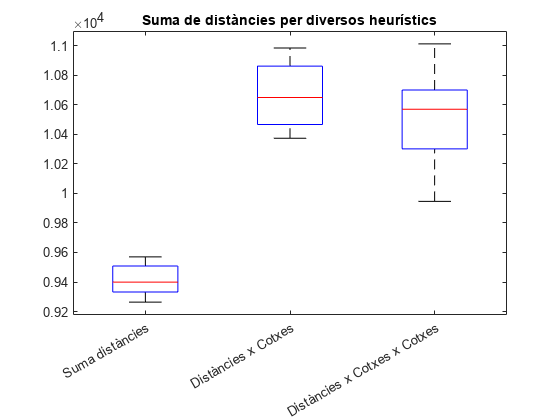


boxplot([Resultats8_Dist.SumaDistancias, Resultats8_Dist.x_Coches, Resultats8_Dist.x_Coches_2],'Labels',{'Suma distàncies','Distàncies x Cotxes', 'Distàncies x Cotxes x Cotxes'});
title("Suma de distàncies per diversos heurístics");


Resultats8_Temps = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 8 Temps", "ReadVariableNames",true);

Resultats8_Temps = Resultats8_Temps(1:10, 1:4)

Resultats8_Temps = 10×4 table
    Seed_Temps    SumaDistancias    x_Coches    x_Coches_2
    __________    ______________    ________    __________

     1.342e+05         2029           2025         2188   
    9.4533e+05         1792           2409         2158   
    1.4417e+06         1835           2461         2141   
    4.0841e+05         1773           1989         1951   
     1.963e+06         1544           1915         1850   
    1.3117e+06         1596           2035         1877   
    2.6156e+06         1510           1938         1843   
    2.7173e+05         1592           1975         1999   
     6.676e+08         1747           1922         1984   
    6.3429e+06         1530           1871         1948   


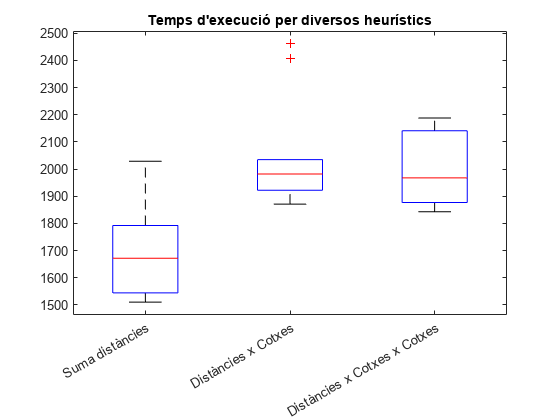


boxplot([Resultats8_Temps.SumaDistancias, Resultats8_Temps.x_Coches, Resultats8_Temps.x_Coches_2],'Labels',{'Suma distàncies','Distàncies x Cotxes', 'Distàncies x Cotxes x Cotxes'});
title("Temps d'execució per diversos heurístics");


Resultats8_Cotxes = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 8 Cotxes", "ReadVariableNames",true);

Resultats8_Cotxes = Resultats8_Cotxes(1:10, 1:4)

Resultats8_Cotxes = 10×4 table
    Seed_Cotxes    SumaDistancias    x_Coches    x_Coches_2
    ___________    ______________    ________    __________

     1.342e+05           61             52           50    
    9.4533e+05           62             49           50    
    1.4417e+06           58             50           54    
    4.0841e+05           58             51           48    
     1.963e+06           62             50           50    
    1.3117e+06           60             49           51    
    2.6156e+06           60             49           50    
    2.7173e+05           57             50           52    
     6.676e+08           52             50           49    
    6.3429e+06           61             51           48    


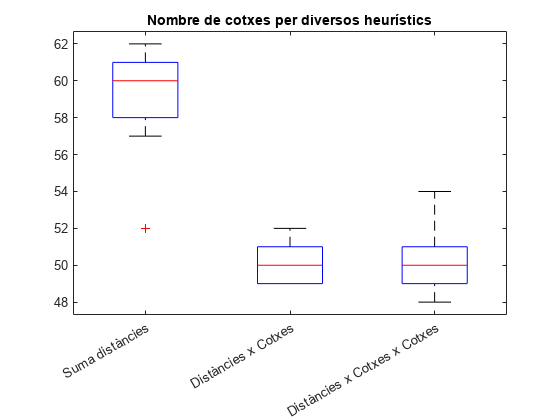


boxplot([Resultats8_Cotxes.SumaDistancias, Resultats8_Cotxes.x_Coches, Resultats8_Cotxes.x_Coches_2],'Labels',{'Suma distàncies','Distàncies x Cotxes', 'Distàncies x Cotxes x Cotxes'});
title("Nombre de cotxes per diversos heurístics");


[hd1,pd1, intervald1, statsd1] = ttest(Resultats8_Dist.SumaDistancias, Resultats8_Dist.x_Coches)

hd1 = 1

pd1 = 1.1599e-08

intervald1 = 1.0e+03 *

   -1.3780
   -1.0908


statsd1 = struct with fields:
    tstat: -19.4521
       df: 9
       sd: 200.6734


[hd2,pd2, intervald2, statsd2] = ttest(Resultats8_Dist.x_Coches, Resultats8_Dist.x_Coches_2)

hd2 = 0

pd2 = 0.2241

intervald2 =   -95.4900
  356.0900


statsd2 = struct with fields:
    tstat: 1.3055
       df: 9
       sd: 315.6327


[hd3,pd3, intervald3, statsd3] = ttest(Resultats8_Dist.SumaDistancias, Resultats8_Dist.x_Coches_2)

hd3 = 1

pd3 = 3.4902e-07

intervald3 = 1.0e+03 *

   -1.2939
   -0.9143


statsd3 = struct with fields:
    tstat: -13.1624
       df: 9
       sd: 265.2611



[ht1,pt1, intervalt1, statst1] = ttest(Resultats8_Temps.SumaDistancias, Resultats8_Temps.x_Coches)

ht1 = 1

pt1 = 2.3552e-04

intervalt1 =  -497.4472
 -220.9528


statst1 = struct with fields:
    tstat: -5.8776
       df: 9
       sd: 193.2562


[ht2,pt2, intervalt2, statst2] = ttest(Resultats8_Temps.x_Coches, Resultats8_Temps.x_Coches_2)

ht2 = 0

pt2 = 0.2405

intervalt2 =   -48.0893
  168.2893


statst2 = struct with fields:
    tstat: 1.2566
       df: 9
       sd: 151.2382


[ht3,pt3, intervalt3, statst3] = ttest(Resultats8_Temps.SumaDistancias, Resultats8_Temps.x_Coches_2)

ht3 = 1

pt3 = 1.9900e-06

intervalt3 =  -362.1781
 -236.0219


statst3 = struct with fields:
    tstat: -10.7266
       df: 9
       sd: 88.1772



[hc1,pc1, intervalc1, statsc1] = ttest(Resultats8_Temps.SumaDistancias, Resultats8_Temps.x_Coches)

hc1 = 1

pc1 = 2.3552e-04

intervalc1 =  -497.4472
 -220.9528


statsc1 = struct with fields:
    tstat: -5.8776
       df: 9
       sd: 193.2562


[hc2,pt2, intervalc2, statsc2] = ttest(Resultats8_Temps.x_Coches, Resultats8_Temps.x_Coches_2)

hc2 = 0

pt2 = 0.2405

intervalc2 =   -48.0893
  168.2893


statsc2 = struct with fields:
    tstat: 1.2566
       df: 9
       sd: 151.2382


[hc3,pc3, intervalc3, statsc3] = ttest(Resultats8_Temps.SumaDistancias, Resultats8_Temps.x_Coches_2)

hc3 = 1

pc3 = 1.9900e-06

intervalc3 =  -362.1781
 -236.0219


statsc3 = struct with fields:
    tstat: -10.7266
       df: 9
       sd: 88.1772


Experiment 9

Resultats9_1 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 9", "ReadVariableNames",true);

Resultats9_1 = Resultats9_1(1:10, 1:11)

Resultats9_1 = 10×11 table
    Seed_Persones    x200    x250    x300    x350    x400    x450    x500    x550    x600    x650
    _____________    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

          32764       47      61      70      87      96     110     119     129     144     154 
         230800       49      60      75      85      98     107     121     131     141     155 
         351990       47      66      74      87      96     105     126     137     144     154 
          99711       50      60      70      80      96     106     118     131     144     157 
         4

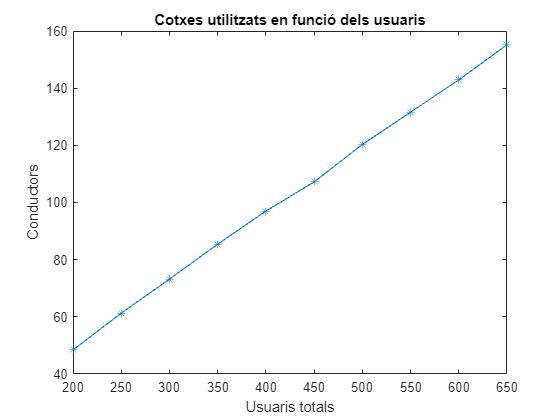


Personas = [200 250 300 350 400 450 500 550 600 650];
Cotxes = [mean(Resultats9_1.x200) mean(Resultats9_1.x250) mean(Resultats9_1.x300) mean(Resultats9_1.x350) mean(Resultats9_1.x400) mean(Resultats9_1.x450) mean(Resultats9_1.x500) mean(Resultats9_1.x550) mean(Resultats9_1.x600) mean(Resultats9_1.x650)];
%g = polyfit(Personas, Cotxes, 1)
Ratio = Personas./Cotxes;
%x = linspace(200, 650, 1000);
plot(Personas, Cotxes, "*-");
title("Cotxes utilitzats en funció dels usuaris");
xlabel("Usuaris totals");
ylabel("Conductors");

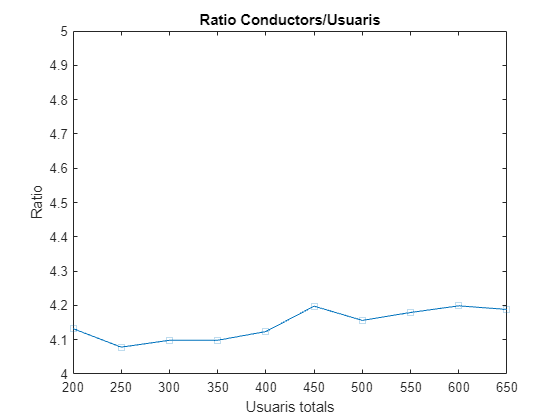


plot(Personas, Ratio, "s-");
title("Ratio Conductors/Usuaris");
xlabel("Usuaris totals");
ylabel("Ratio");
ylim([4.0, 5.0]);

format long
RatioMitg = mean(Ratio)

RatioMitg =    4.145122066794428


Resultats9_Dist = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 9_1", "ReadVariableNames",true);

Resultats9_Dist = Resultats9_Dist(1:10, 1:11)

Resultats9_Dist = 10×11 table
    Seed_Persones    x200     x250     x300     x350     x400     x450     x500     x550     x600     x650 
    _____________    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____

          32764      10579    12824    14738    17676    20261    22524    24731    27492    28945    31219
         230800      11272    12929    15207    17768    19720    22479    23850    27317    29478    31097
         351990      10412    13908    15556    17886    19052    22026    24174    27466    28103    31333
          99711      10410    13241    15059    17186  

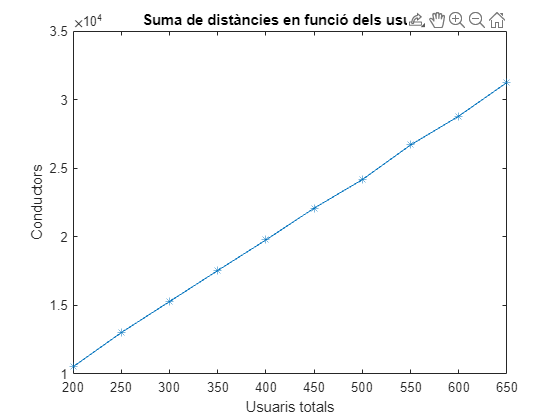

Distancias = [mean(Resultats9_Dist.x200) mean(Resultats9_Dist.x250) mean(Resultats9_Dist.x300) mean(Resultats9_Dist.x350) mean(Resultats9_Dist.x400) mean(Resultats9_Dist.x450) mean(Resultats9_Dist.x500) mean(Resultats9_Dist.x550) mean(Resultats9_Dist.x600) mean(Resultats9_Dist.x650)];
RatioDist = Distancias./Personas;

plot(Personas, Distancias, "*-");
title("Suma de distàncies en funció dels usuaris");
xlabel("Usuaris totals");
ylabel("Distàncies");

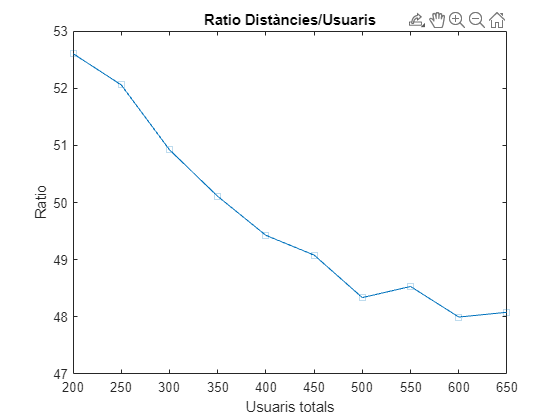


plot(Personas, RatioDist, "s-");
title("Ratio Distàncies/Usuaris");
xlabel("Usuaris totals");
ylabel("Ratio");

%ylim([4.0, 5.0]);
format long
RatioMitgDist = mean(RatioDist)

RatioMitgDist =   49.714433260628262


Resultats9_2 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 9_2", "ReadVariableNames",true);

Resultats9_2 = Resultats9_2(1:10, 1:4)

Resultats9_2 = 10×4 table
    Seed_Distancia    SumaDistancias    x_Coches    x_Temps
    ______________    ______________    ________    _______

          32764           10030            48        2047  
         230800           10441            48        1842  
         351990           10388            49        1792  
          99711            9831            48        1720  
         479267           10628            47        2109  
         320254           10111            49        1637  
         638594           10734            49        1835  
          66341           10047            48        1801  
      -23745809           10816            46        2359  
        1548590           10325            46        1975  



Resultats9_3 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 9_3", "ReadVariableNames",true);

Resultats9_3 = Resultats9_3(1:10, 1:4)

Resultats9_3 = 10×4 table
    Seed_Distancia    SumaDistancias    x_Coches    x_Temps
    ______________    ______________    ________    _______

          32764           10418            49        2291  
         230800           10934            50        2067  
         351990           10228            47        1881  
          99711           10123            49        1774  
         479267           10283            51        1772  
         320254           10586            49        1819  
         638594           10961            53        1839  
          66341           10242            50        1932  
      -23745809           10165            50        1821  
        1548590           10114            46        2067  


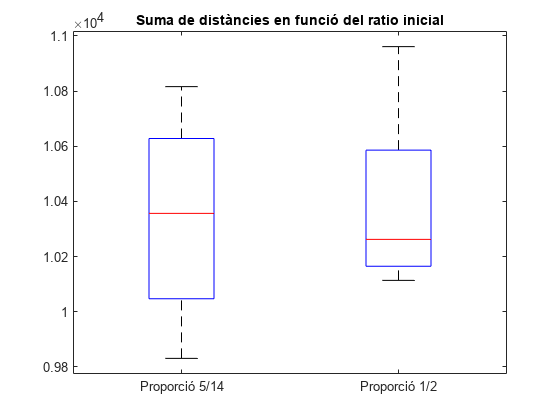


boxplot([Resultats9_2.SumaDistancias, Resultats9_3.SumaDistancias], 'Labels', {'Proporció 5/14', 'Proporció 1/2'});
title("Suma de distàncies en funció del ratio inicial");


[hd, pd, intervd, statsd] = ttest(Resultats9_2.SumaDistancias, Resultats9_3.SumaDistancias)

hd =      0


pd =    0.581068262612437


intervd = 1.0e+02 *

  -3.481314285054730
   2.075314285054729


statsd = struct with fields:
    tstat: -0.572396180663129
       df: 9
       sd: 3.883815563763724e+02


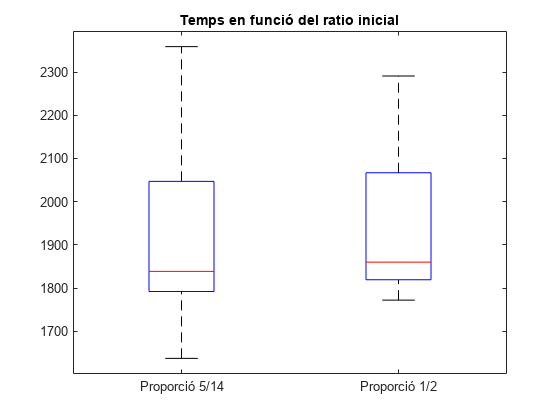


boxplot([Resultats9_2.x_Temps, Resultats9_3.x_Temps], 'Labels', {'Proporció 5/14', 'Proporció 1/2'});
title("Temps en funció del ratio inicial");


[ht, pt, intervt, statst] = ttest(Resultats9_2.x_Temps, Resultats9_3.x_Temps)

ht =      0


pt =    0.859792271427086


intervt = 1.0e+02 *

  -1.963007167024440
   1.671007167024441


statst = struct with fields:
    tstat: -0.181768653290125
       df: 9
       sd: 2.540000874890488e+02


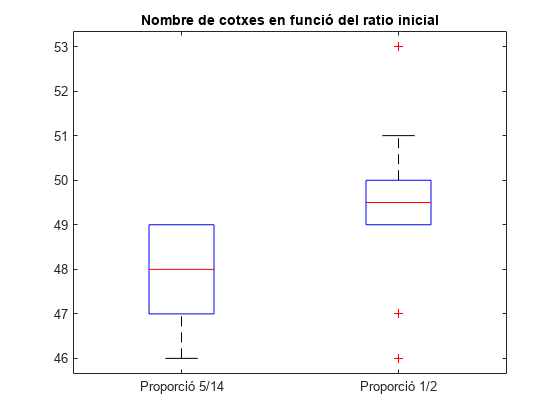


boxplot([Resultats9_2.x_Coches, Resultats9_3.x_Coches], 'Labels', {'Proporció 5/14', 'Proporció 1/2'});
title("Nombre de cotxes en funció del ratio inicial");


[hc, pc, intervc, statsc] = ttest(Resultats9_2.x_Coches, Resultats9_3.x_Coches);

Resultats9_t = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 9_t", "ReadVariableNames",true);

Resultats9_t = Resultats9_t(1:10, 1:11)

Resultats9_t = 10×11 table
    Seed_Persones    x200    x250    x300    x350    x400    x450    x500    x550    x600    x650
    _____________    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

          32764      2332    2196    2370    2847    3039    3239    3516    3831    4001    4339
         230800      2165    2101    2568    2828    2985    3235    3459    3979    4204    4351
         351990      1713    2523    2535    2810    2880    3230    3522    3834    3992    4156
          99711      1852    2205    2649    2772    2950    3201    3712    3665    4094    4250
         4

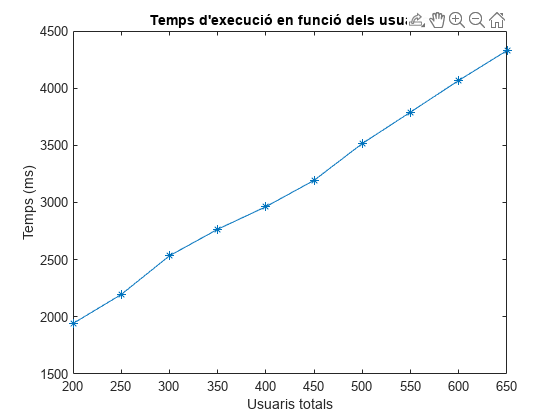


temps = [mean(Resultats9_t.x200) mean(Resultats9_t.x250) mean(Resultats9_t.x300) mean(Resultats9_t.x350) mean(Resultats9_t.x400) mean(Resultats9_t.x450) mean(Resultats9_t.x500) mean(Resultats9_t.x550) mean(Resultats9_t.x600) mean(Resultats9_t.x650)];
plot(Personas, temps, "*-");
title("Temps d'execució en funció dels usuaris");
xlabel("Usuaris totals");
ylabel("Temps (ms)");

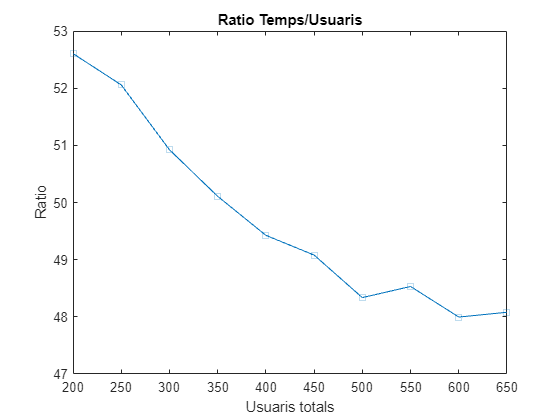


RatioDist = Distancias./Personas;
plot(Personas, RatioDist, "s-");
title("Ratio Temps/Usuaris");
xlabel("Usuaris totals");
ylabel("Ratio");

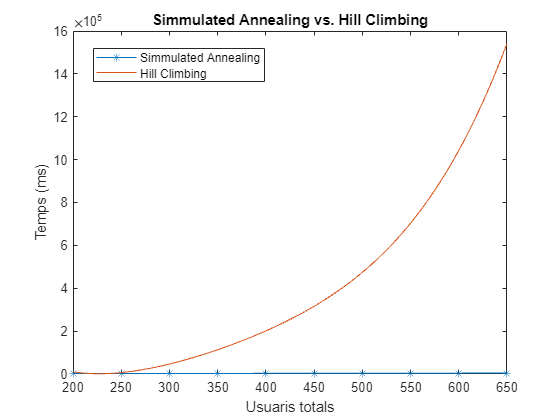


X = linspace(200, 650, 1000);
plot(Personas, temps, "*-", X, polyval(g3, X));
title("Simmulated Annealing vs. Hill Climbing");
xlabel("Usuaris totals");
ylabel("Temps (ms)");
legend("Simmulated Annealing", "Hill Climbing");

legend("Position", [0.16599,0.80437,0.30714,0.082143])

g2 = 1.0e+05 *

    0.0000   -0.0003    0.0847   -8.7606


g3 = 1.0e+06 *

    0.0000   -0.0000    0.0001   -0.0139    1.1759


Sr = 1.0e+10 *

    2.0475    0.2315    0.0138


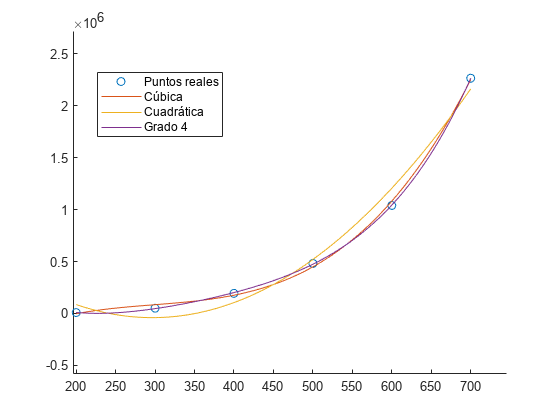

%plot(f);